clear, close all, clc

Anvender data fra opgave 11-11.

load('dataset_problem_11_11.mat')

Opgave a)

Udregn R^2 for denne model. Hvad siger denne værdi?

X = [data(:,2) linspace(1,1,max(size(data)))']

X =    15.5000    1.0000
   23.7500    1.0000
    8.0000    1.0000
   17.0000    1.0000
    5.0000    1.0000
   19.0000    1.0000
   24.0000    1.0000
    2.5000    1.0000
    7.5000    1.0000
   11.0000    1.0000


y = data(:,1)

y = 	1.0e+04 *

    1.4884
    1.1570
    1.5968
    1.4213
    1.5220
    1.1778
    1.2305
    1.7755
    1.6257
    1.5559


[b,~,r,~,STATS] = regress(y,X)

b = 	1.0e+04 *

   -0.0255
    1.8090


r = 	1.0e+03 *

    0.7389
   -0.4744
   -0.0856
    0.4496
   -1.5973
   -1.4756
    0.3239
    0.3008
    0.0760
    0.2692


STATS = 	1.0e+05 *

    0.0000    0.0016    0.0000    4.6101


R2 = STATS(1)

R2 = 0.8969

% Værdien er 0,9, og er derfor nogenlunde præcis.

Opgave b)

Plot residualerne på et normalplot. Ser det rigtigt ud?

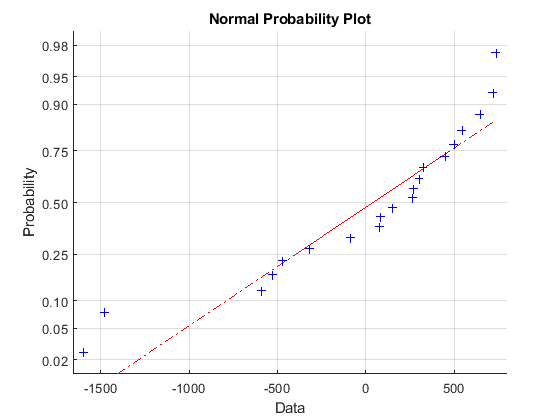

normplot(r)

% Halerne ser helt forkerte ud.

Opgave c)

Fjern de tre problempunkter fra opgave b og lav regression, R^2 igen.

[~,A] = sort(r)

A =      5
     6
    12
    20
     2
    15
     3
     9
    17
    11


x = data(:,2)

x =    15.5000
   23.7500
    8.0000
   17.0000
    5.0000
   19.0000
   24.0000
    2.5000
    7.5000
   11.0000


[yc,xc] = deal(y(A),x(A))

yc = 	1.0e+04 *

    1.5220
    1.1778
    1.6544
    1.2091
    1.1570
    1.2171
    1.5968
    1.6257
    1.6647
    1.4929


xc =     5.0000
   19.0000
    3.7500
   21.5000
   23.7500
   22.0000
    8.0000
    7.5000
    6.0000
   13.0000


[yc,xc] = deal(yc(3:19),xc(3:19))

yc = 	1.0e+04 *

    1.6544
    1.2091
    1.1570
    1.2171
    1.5968
    1.6257
    1.6647
    1.4929
    1.5172
    1.5559


xc =     3.7500
   21.5000
   23.7500
   22.0000
    8.0000
    7.5000
    6.0000
   13.0000
   12.5000
   11.0000


Xc = [xc linspace(1,1,17)']

Xc =     3.7500    1.0000
   21.5000    1.0000
   23.7500    1.0000
   22.0000    1.0000
    8.0000    1.0000
    7.5000    1.0000
    6.0000    1.0000
   13.0000    1.0000
   12.5000    1.0000
   11.0000    1.0000


[~,~,~,~,STATSc] = regress(yc,Xc)

STATSc = 	1.0e+05 *

    0.0000    0.0039    0.0000    1.7730


R2c = STATSc(1)

R2c = 0.9628

% Den nye R^2 er 0,96 og altså noget højere, da
% summen af residualer er noget mindre.

Opgave d)

Ændredes værdien af sigma_2_hat, da de 3 problempunkter blev fjernet? Hvorfor?

sigma_2_hat_a = STATS(4)

sigma_2_hat_a = 4.6101e+05

sigma_2_hat_c = STATSc(4)

sigma_2_hat_c = 1.7730e+05

% Variansen er altså blevet betydelig mindre
% Igen fordi afvigerne er blevet fjernet